# Calculate trip direction

`taxiTable = addCrowDirection(taxiTable)` adds the feature `CrowDirection` to `taxiTable`. This feature represents the direction of travel, and is found by taking the angle between North and the line connecting trip pick up and drop off locations (see image below). It is calculated from the features `PickupLat`, `PickupLon`, `DropoffLat`, `and` `DropoffLon` using the [`distance`](https://www.mathworks.com/help/map/ref/distance.html) function. 

`CrowDirection` is in units of degrees and increases clockwise from North.

### 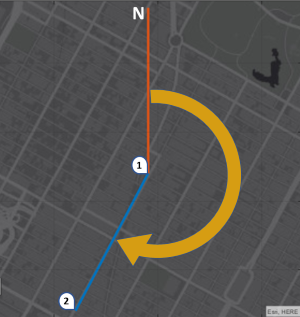

#### See Also

[distance](https://www.mathworks.com/help/map/ref/distance.html)

function taxiTable = addCrowDirection(taxiTable)
% Compute the trip azimuth
[~,az] = distance(taxiTable.PickupLat, taxiTable.PickupLon, taxiTable.DropoffLat, taxiTable.DropoffLon);
taxiTable.CrowDirection = az;
end